Antanas Mantas Juodeikis Ef-25/1

3 variantas

papildomos 23 variantas

2026-09-24

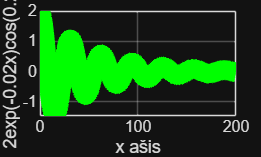

clear
close all
syms z
figure(1)
x = linspace(0, 200, 300);
y = 2*exp(x.*-0.02).*cos(x.*0.2);
plot(x, y, 'g', LineWidth=10)

figure(2)
hold on
fplot(cot(z), [-pi 0])
fplot(cot(z), [0 pi])

figure(1)
grid on
xlabel("x ašis")
ylabel("2exp(-0.02x)cos(0.2x)")
ylim([min(y) max(y)])

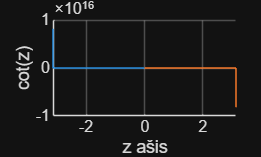


figure(2)
grid on
xlabel("z ašis")
ylabel("cot(z)")

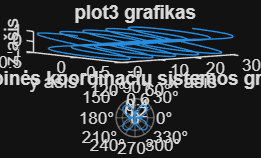

clear
close all
x = 0:0.01*pi:10*pi;
y = sin(x).*cos(x);
z = cos(x);

subplot(2,1,1);
plot3(x,y,z);

subplot(2,1,2);
polarplot(x,y);

subplot(2,1,1);
title("plot3 grafikas")
xlabel("x ašis")
ylabel("y ašis")
zlabel("z ašis")

subplot(2,1,2);
title("kampinės koordinačių sistemos grafikas");

doc polaraxes

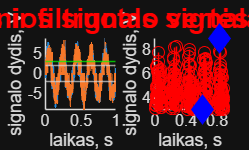

clear
close all
t = 0:0.001:1;
A = 5;
f = 5;
o = 1.5;
U1 = 3;
U2 = 2;
s = A*sin(2*pi*f*t);
n = o*randn(size(t));
s = s+n;

figure(1)
subplot(1,2,1)
hold on
plot(t, s, LineWidth=1)
filt = s;
filt(abs(filt)<U2) = 0;
plot(t, filt, '--', LineWidth=1)
yline(U1, 'g')
yline(U2)
yline(-U2)
ylim([min(filt) max(filt)])

title("Pradinis ir filtruotas signalai", Color='r', FontSize=14, FontWeight="bold")
xlabel("laikas, s")
ylabel("signalo dydis, V")

subplot(1,2,2)
hold on
stem(t(s>U1), s(s>U1), "r")
ylim([min(s(s>U1)) max(s(s>U1))])
plot(t(s == min(s(s>U1))), min(s(s>U1)), "diamond", MarkerSize=10, Color='b', MarkerFaceColor='b')
plot(t(s == max(s(s>U1))), max(s(s>U1)), "diamond", MarkerSize=10, Color='b', MarkerFaceColor='b')

title("Pradinios signalo vertės viršijančios U1", Color='r', FontSize=14, FontWeight="bold")
xlabel("laikas, s")
ylabel("signalo dydis, V")